# Butterfly Effect Simulator

## Euler's method equations

sigma = 10; rho = 28; beta = 8/3;
dt = 0.001;
x0 = 1; y0 = 0.5; z0 = 0.3;
tspan = 0:dt:100;
x = zeros(size(tspan)); y = x; z = x;
x(1) = x0; y(1) = y0; z(1) = z0;

for j = 1:length(tspan)-1
    x(j+1) = x(j) + sigma*(y(j)-x(j))*dt;
    y(j+1) = y(j) + (x(j)*(rho-z(j))-y(j))*dt;
    z(j+1) = z(j) + (x(j)*y(j)-beta*z(j))*dt;
end

## Plot x(t), y(t), z(t) using Euler's method

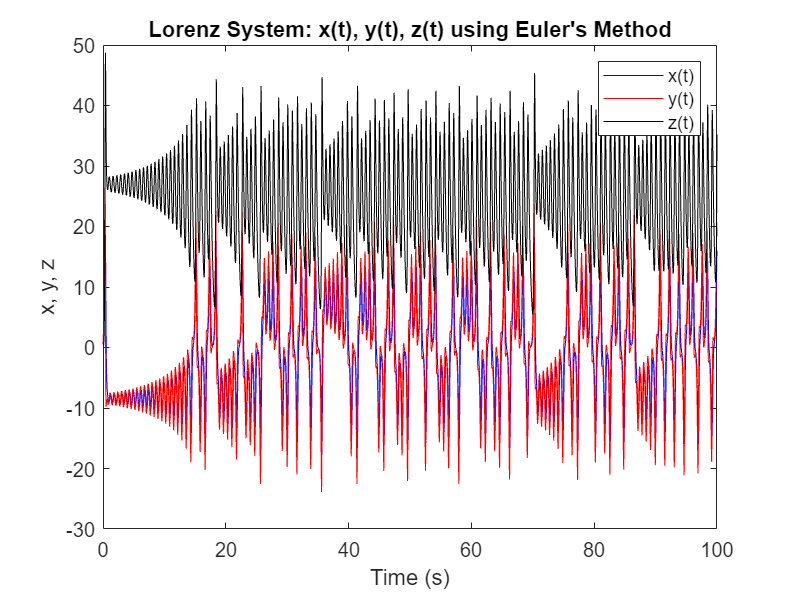

figure;
plot(tspan,x,'b-',tspan,y,'r-',tspan,z,'k-');
xlabel('Time (s)'); ylabel('x, y, z');
title('Lorenz System: x(t), y(t), z(t) using Euler''s Method');
legend('x(t)','y(t)','z(t)');

## Strange attractors using Euler's method

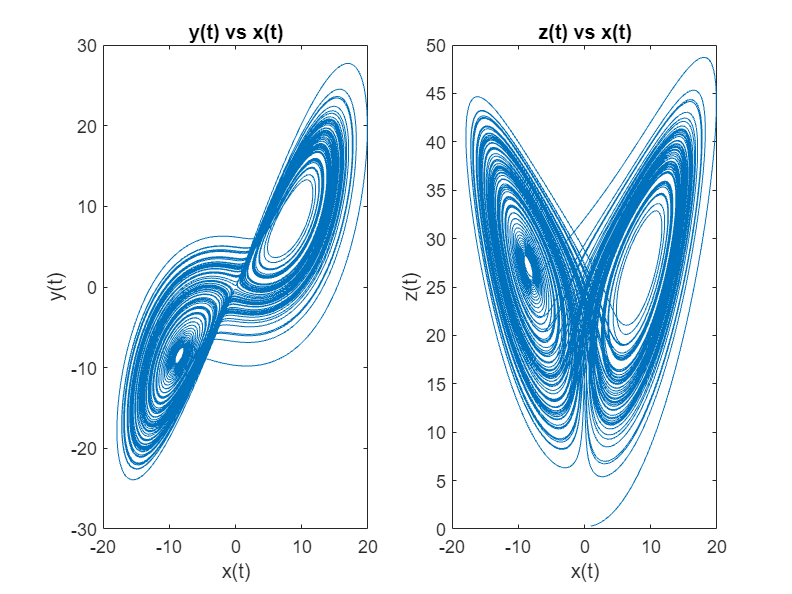

figure;
subplot(1,2,1); plot(x,y); xlabel('x(t)'); ylabel('y(t)'); title('y(t) vs x(t)');
subplot(1,2,2); plot(x,z); xlabel('x(t)'); ylabel('z(t)'); title('z(t) vs x(t)');

## 3D trajectory using Euler's method

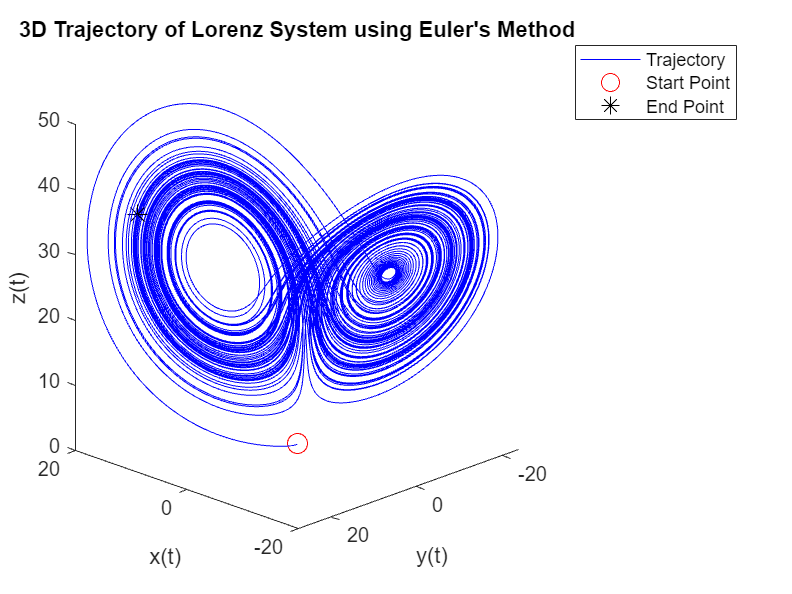

figure;
plot3(x,y,z,'b-');
hold on;
plot3(x0,y0,z0,'ro','MarkerSize',10); % start point
plot3(x(end),y(end),z(end),'k*','MarkerSize',10); % end point
hold off;
xlabel('x(t)'); ylabel('y(t)'); zlabel('z(t)');
title('3D Trajectory of Lorenz System using Euler''s Method');
legend('Trajectory','Start Point','End Point');
view([-135.4 18.9])


% Finding the distance between the start and end points
distance = sqrt((x0-x(end))^2 + (y0-y(end))^2 + (z0-z(end))^2);
fprintf('Distance between start and end points: %.4f\n', distance);

Distance between start and end points: 41.9562


## Examining sensitivity to changes

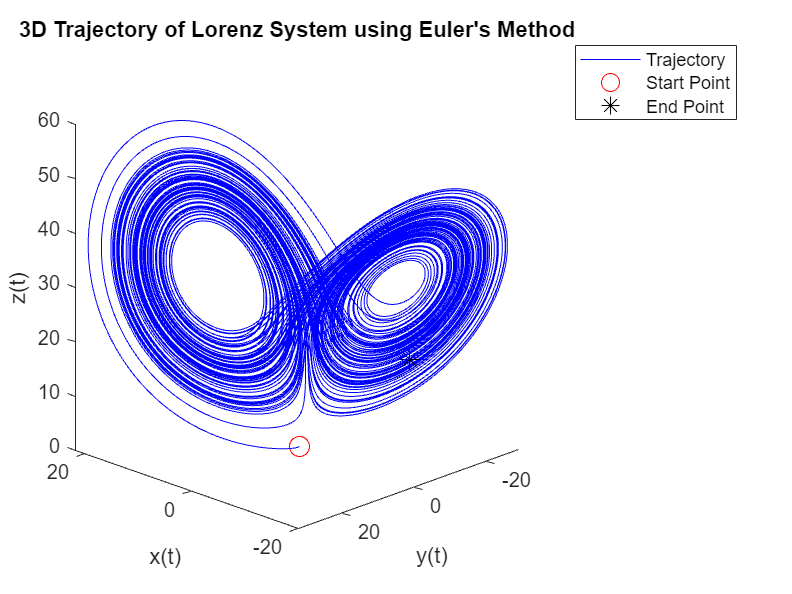

% Altered Lorenz Equation parameters and starting points
sigma = 9; rho = 32; beta = 10/3;
dt = 0.001;
x0 = 1; y0 = 0.5; z0 = 0.31;
tspan = 0:dt:100;
x = zeros(size(tspan)); y = x; z = x;
x(1) = x0; y(1) = y0; z(1) = z0;

for j = 1:length(tspan)-1
    x(j+1) = x(j) + sigma*(y(j)-x(j))*dt;
    y(j+1) = y(j) + (x(j)*(rho-z(j))-y(j))*dt;
    z(j+1) = z(j) + (x(j)*y(j)-beta*z(j))*dt;
end

figure;
plot3(x,y,z,'b-');
hold on;
plot3(x0,y0,z0,'ro','MarkerSize',10); % start point
plot3(x(end),y(end),z(end),'k*','MarkerSize',10); % end point
hold off;
xlabel('x(t)'); ylabel('y(t)'); zlabel('z(t)');
title('3D Trajectory of Lorenz System using Euler''s Method');
legend('Trajectory','Start Point','End Point');
view([-135.4 18.9])


% Finding the distance between the start and end points
distance = sqrt((x0-x(end))^2 + (y0-y(end))^2 + (z0-z(end))^2);
fprintf('Distance between start and end points: %.4f\n', distance);

Distance between start and end points: 24.5844


## 4th Order Runge-Kutta method

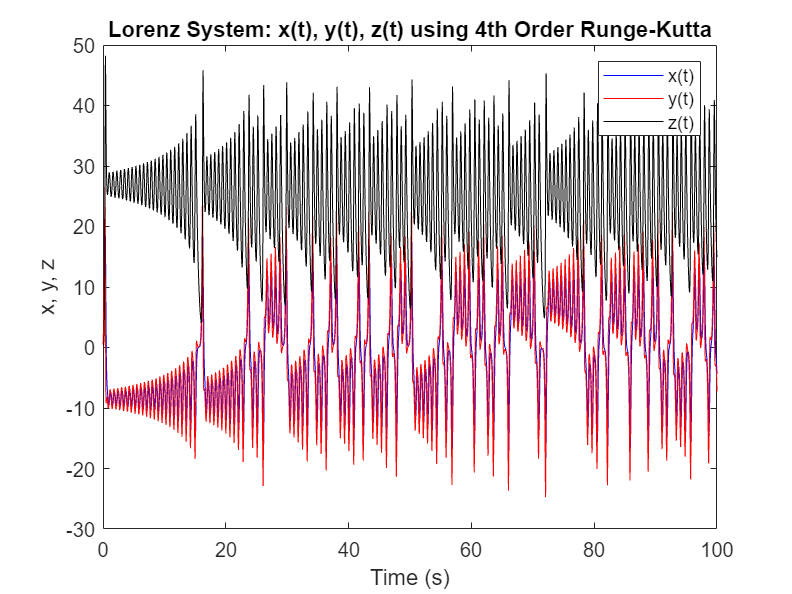

% Solve using 4th order Runge-Kutta
sigma = 10; rho = 28; beta = 8/3;
x0 = 1; y0 = 0.5; z0 = 0.3;
tspan = 0:0.001:100;
[x, y, z] = rk4(x0, y0, z0, tspan, sigma, rho, beta);

% Plot x(t), y(t), z(t) using 4th order Runge-Kutta
figure;
plot(tspan,x,'b-',tspan,y,'r-',tspan,z,'k-');
xlabel('Time (s)'); ylabel('x, y, z');
title('Lorenz System: x(t), y(t), z(t) using 4th Order Runge-Kutta');
legend('x(t)','y(t)','z(t)');

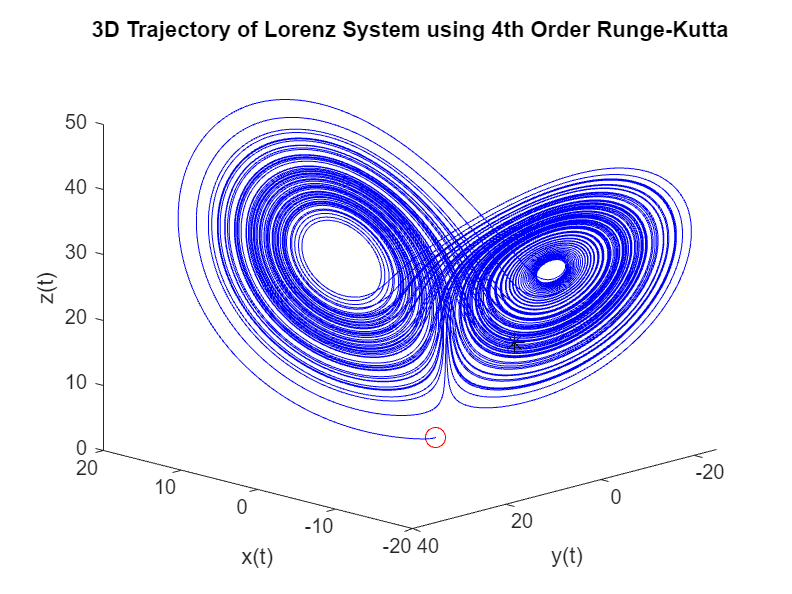


figure;
plot3(x,y,z,'b-');
hold on;
plot3(x0,y0,z0,'ro','MarkerSize',10); % start point
plot3(x(end),y(end),z(end),'k*','MarkerSize',10); % end point
hold off;
view([-135.4 18.9])
xlabel('x(t)'); ylabel('y(t)'); zlabel('z(t)');
title('3D Trajectory of Lorenz System using 4th Order Runge-Kutta');